fname = 'netlist.cir';
scam;



Started -- please be patient.

Done! Elapsed time = 0.581537 seconds.

Netlist
     V1 0 1 1
     L1 1 2 0.1
     C1 2 0 0.1
     I1 2 0 1
     R 2 3 4
     C2 3 0 0.1
     I2 0 3 1
     L2 3 4 0.1
     V2 4 0 1
 
Solved variables:


$$\left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ v_{4}\\ I_{\mathrm{V1}}\\ I_{\mathrm{V2}} \end{array}\right)$$

L1 = sym('L1');
L2 = sym('L2');
V1 = sym('V1');
V2 = sym('V2');
I1 = sym('I1');
I2 = sym('I2');
D1 = sym('D1');
D2 = sym('D2');
d = sym('d');
H = v_2-v_3;
H = subs(H, L1, L1/D1^2);
H = subs(H, L2, L2/D2^2);
H = subs(H, V1, V1/D1*d);
H = subs(H, V2, V2/D2*d);
H = subs(H, I1, I1*d);
H = subs(H, I2, I2*d);
H=H/d;
H=simplifyFraction(H);
H=collect(H)

$$H = \frac{\left(-C_{1}\,I_{2}\,L_{1}\,L_{2}\,R-C_{2}\,I_{1}\,L_{1}\,L_{2}\,R\right)\,s^{3}+\left(-C_{1}\,D_{2}\,L_{1}\,R\,V_{2}-C_{2}\,D_{1}\,L_{2}\,R\,V_{1}\right)\,s^{2}+\left(-I_{2}\,L_{2}\,R\,{D_{1}}^{2}-I_{1}\,L_{1}\,R\,{D_{2}}^{2}\right)\,s-R\,V_{2}\,{D_{1}}^{2}\,D_{2}-R\,V_{1}\,D_{1}\,{D_{2}}^{2}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,R\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}+C_{2}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{2}\,L_{2}\,R\,{D_{1}}^{2}+C_{1}\,L_{1}\,R\,{D_{2}}^{2}\right)\,s^{2}+\left(L_{2}\,{D_{1}}^{2}+L_{1}\,{D_{2}}^{2}\right)\,s+{D_{1}}^{2}\,{D_{2}}^{2}\,R}$$

%lt = latex(H);

syms C1 C2 R R2 Vg
[Hn, Hd] = numden(H);

I1n = (V1-V2)/(D1*R);
I2n = (V1-V2)/(D2*R);

D1n = 0.5;
D2n = 0.5;

Hn = subs(Hn, [I1, I2], [I1n, I2n]);
Hn = subs(Hn, [V1, V2], [1/D1, 1/D2]);
Hn = subs(Hn, [C1, C2, L1, L2, R, R2, D1, D2],...
    [1e-6, 1e-6, 64e-6, 64e-6, 4, 1000, D1n, D2n])

$$Hn = -\frac{s^{2}}{1953125000}-2$$


Hd = subs(Hd, [I1, I2], [I1n, I2n]);
Hd = subs(Hd, [V1, V2], [1/D1, 1/D2]);
Hd = subs(Hd, [C1, C2, L1, L2, R, R2 D1, D2],...
    [1e-6, 1e-6, 64e-6, 64e-6, 4, 1000, D1n, D2n])

$$Hd = \frac{s^{4}}{61035156250000000000}+\frac{s^{3}}{122070312500000}+\frac{s^{2}}{7812500000}+\frac{s}{31250}+\frac{1}{4}$$


nc = sym2poly(Hn)

nc =    -0.0000         0   -2.0000


dc = sym2poly(Hd)

dc =     0.0000    0.0000    0.0000    0.0000    0.2500


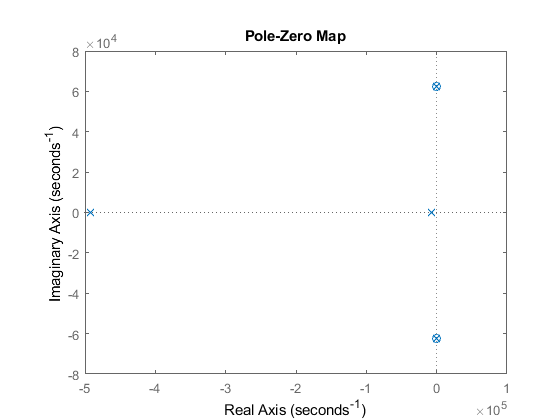


Htf = tf(nc, dc);
pzmap(Htf);